% Part 2: Compartment Modeling of COVID-19
clear;clc;close all

% 1
% Alameda County

#### AC 2a.

Run the function by executing the following code:

clear;clc;close all
Apop = 1685886; % population of AC at day 0 of the outbreak
pop0 = [1-(10/Apop),10/Apop,0];
mu = 1/3;
beta = 1/2;
SIRmodel([],pop0,beta,mu)

ans = 1.0e-05 *

   -0.2966
    0.0989
    0.1977


#### AC 2b.

Dpop significance of the positive and negative signs.

**The resulting output of the SIRmodel (dpop) is a 3x1 vector holding the rate of change values (ds/dt, di/dt, dr/dt) which are the following: 10^-5 * [-0.2966, 0.0989, 0.1977]. The positive value signs mean that these population have an initial increase and then an eventual plateau and the negative signs mean that there is an initial decrease that is constant until the proportion approaches zero or eventual plateau. **

#### AC 3c. 

Euler’s method is a numerical solution method for a system of differential equations. If we know **y****o** (i.e. **i(0)**, **r(0)**, and **s(0)**) and we have a way to calculate **dy/dt** at any point (***t***,***y***) (i.e. dpop), then it follows that we can calculate a sequence of y-values from the “slope and intercept equation”:


$$y_n =y_{n-1} +{\left(\frac{\textrm{dy}}{\textrm{dt}}\right)}_{n-1} *\Delta t$$


where $\Delta$t is a small change in time. For the SIR model, we want the dependent variables to be **s**, **i**, and **r**. Use the following script to apply Euler’s method to the SIR model function. 

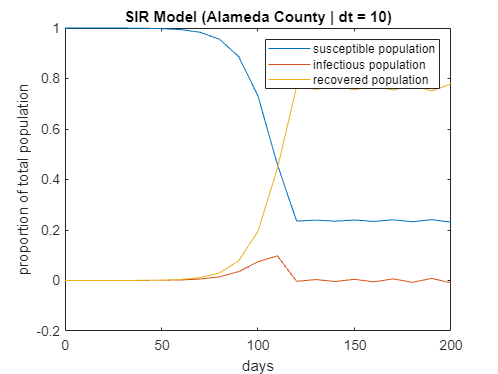

%Euler's Method
dt = 10;			% let delta t = 10 days 
tspan = 0:dt:200;		% let t range up to 200 days
POP(:,1) = pop0;		% POP is the matrix of population data
for i = 1:(200/dt)		% forward euler in a for loop
    POP(:,i+1) = POP(:,i) + dt * SIRmodel(tspan, POP(:,i),beta,mu);
end

% Display a graphical solution of s, i, and r (POP(1,:), POP(2,:),POP(3,:)) 
% on a single plot. Write the commands in the space below. Add all
% formatting to the plot to make sure it is readable and appropriate.


plot(tspan, POP(1, :), tspan, POP(2, :), tspan, POP(3, :));
legend('susceptible population', 'infectious population', 'recovered population');
xlabel('days');
ylabel('proportion of total population');
title('SIR Model (Alameda County | dt = 10)');

#### AC 3d. 

Change $\Delta$**t** to **1** day and replot the solutions in the script below.

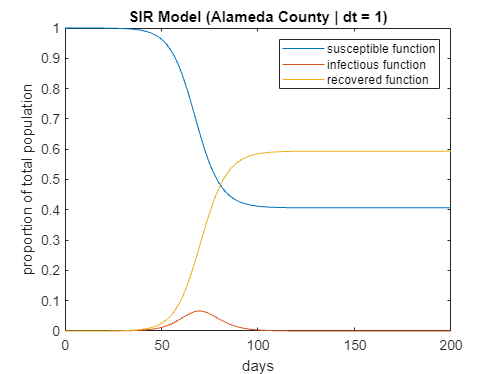

dt = 1;			        % let delta t= 10 days 
tspan = 0:dt:200;		% let t range up to 200 days
POP(:,1) = pop0;		% POP is the matrix of population data
for i = 1:(200/dt)		% forward euler in a for loop
    		POP(:,i+1) = POP(:,i) + dt * SIRmodel(tspan, POP(:,i),beta,mu);
end

% Display a graphical solution of s, i, and r (POP(1,:), POP(2,:),POP(3,:)) 
% on a single plot. Write the commands in the space below. Add all
% formatting to the plot to make sure it is readable and appropriate.

plot(tspan, POP(1, :), tspan, POP(2, :), tspan, POP(3, :));
legend('susceptible function', 'infectious function', 'recovered function');
xlabel('days');
ylabel('proportion of total population');
title('SIR Model (Alameda County | dt = 1)');

#### AC 3e.

Observations in comparison to the previous solution:

**When the **$\Delta$**t = 1, we have a much smoother visual of the depiction of the proportion of each category as percentages of data are given for each day instead of every 10 days. In the previous solution, the graphs would start out smooth but eventually follow a sharp/rigid pattern one rates of change increased/decreased, whereas it is smooth and detailed throughout the entire second solution.**

%% SirModel for Alameda County
[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3))
xlabel('Time')
ylabel('Population')
title('ode45 (Alameda County)')
legend('s(t)','i(t)','r(t), ')

#### AC 3f.

Take the output of the infected population and find its maximum over the region of interest. 

% find the maximum of the infected population (both the value and the location in the array)
[maxinfec, maxloc] = max(pop(:, 2));
% max infection value = 0.0630 and max infection index = 66

% plot the location and value of the maximum as a single (x,y) coordinate pair on the previous plot
hold on
plot(maxloc, maxinfec, 'o')
hold off


% Part 3: Compartment Modeling of COVID-19
clear;clc;close all
% 1
% New York

#### NY 3a.

Run the function by executing the following code:

clear;clc;close all
NYpop = 8773000; % population of NY at day 0 of the outbreak
pop0 = [1-(10/NYpop),10/NYpop,0];
mu = 1/3;
beta = 1/2;
SIRmodel([],pop0,beta,mu)

ans = 1.0e-06 *

   -0.5699
    0.1900
    0.3800


#### NY 3b.

Dpop significance of the positive and negative signs:

**The resulting output of the SIRmodel (dpop) is a 3x1 vector holding the rate of change values (ds/dt, di/dt, dr/dt) which are the following: 10^-6 * [-0.5699, 0.1900, 0.3800]. The positive value signs mean that these population have an initial increase and then an eventual plateau and the negative signs mean that there is an initial decrease that is constant until the proportion approaches zero or eventual plateau. **

#### NY 3c. 

Euler’s method is a numerical solution method for a system of differential equations. If we know **y****o** (i.e. **i(0)**, **r(0)**, and **s(0)**) and we have a way to calculate **dy/dt** at any point (***t***,***y***) (i.e. dpop), then it follows that we can calculate a sequence of y-values from the “slope and intercept equation”:


$$y_n =y_{n-1} +{\left(\frac{\textrm{dy}}{\textrm{dt}}\right)}_{n-1} *\Delta t$$


where $\Delta$t is a small change in time. For the SIR model, we want the dependent variables to be **s**, **i**, and **r**. Use the following script to apply Euler’s method to the SIR model function. 

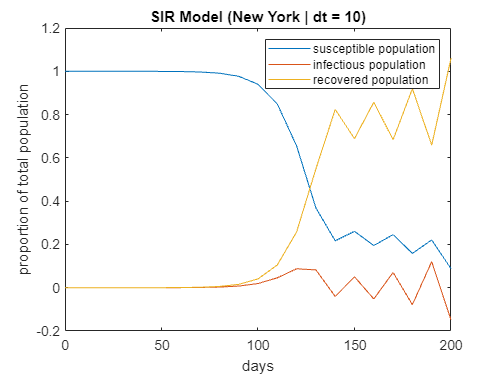

%Euler's Method
dt = 10;			% let delta t = 10 days 
tspan = 0:dt:200;		% let t range up to 200 days
POP(:,1) = pop0;		% POP is the matrix of population data
for i = 1:(200/dt)		% forward euler in a for loop
    POP(:,i+1) = POP(:,i) + dt * SIRmodel(tspan, POP(:,i),beta,mu);
end

% Display a graphical solution of s, i, and r (POP(1,:), POP(2,:),POP(3,:)) 
% on a single plot. Write the commands in the space below. Add all
% formatting to the plot to make sure it is readable and appropriate.


plot(tspan, POP(1, :), tspan, POP(2, :), tspan, POP(3, :));
legend('susceptible population', 'infectious population', 'recovered population');
xlabel('days');
ylabel('proportion of total population');
title('SIR Model (New York | dt = 10)');

#### NY 3d. 

Change $\Delta$**t** to **1** day and replot the solutions in the script below.

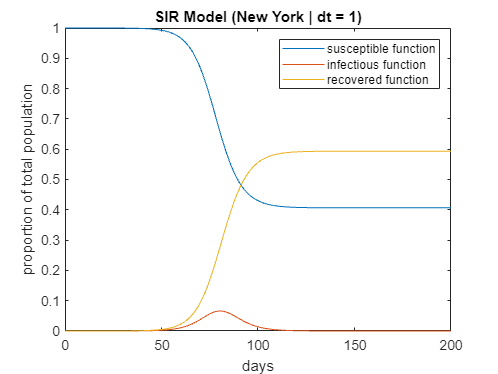

dt = 1;			        % let delta t= 10 days 
tspan = 0:dt:200;		% let t range up to 200 days
POP(:,1) = pop0;		% POP is the matrix of population data
for i = 1:(200/dt)		% forward euler in a for loop
    		POP(:,i+1) = POP(:,i) + dt * SIRmodel(tspan, POP(:,i),beta,mu);
end

% Display a graphical solution of s, i, and r (POP(1,:), POP(2,:),POP(3,:)) 
% on a single plot. Write the commands in the space below. Add all
% formatting to the plot to make sure it is readable and appropriate.

plot(tspan, POP(1, :), tspan, POP(2, :), tspan, POP(3, :));
legend('susceptible function', 'infectious function', 'recovered function');
xlabel('days');
ylabel('proportion of total population');
title('SIR Model (New York | dt = 1)');

#### NY 3e.

Observations in comparison to the previous solution:

**When the **$\Delta$**t = 1, we have a much smoother visual of the depiction of the proportion of each category as percentages of data are given for each day instead of every 10 days. In the previous solution, the graphs would start out smooth but eventually follow a zig-zag pattern one rates of change increased/decreased, whereas it is smooth and detailed throughout the entire second solution.**

#### NY 3f.

**The previous solution and the ode45 are identical in visual output and match the same shape and axes. **

%% New York Sir Model
[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3))
xlabel('Time')
ylabel('Population')
title('ode45 (New York)')
legend('s(t)','i(t)','r(t), ')

#### NY 3h.

Take the output of the infected population and find its maximum over the region of interest. 

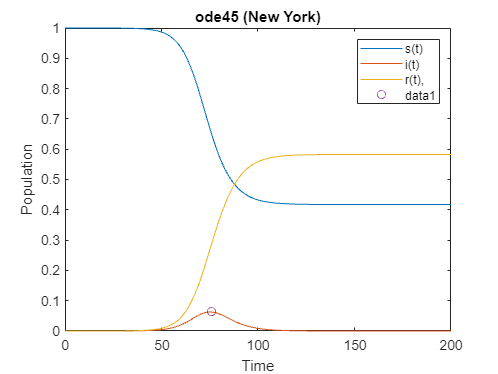

% find the maximum of the infected population (both the value and the location in the array)
[maxinfec, maxloc] = max(pop(:, 2));
% max infection value = 0.0630 and max infection index = 76

% plot the location and value of the maximum as a single (x,y) coordinate pair on the previous plot
hold on
plot(maxloc, maxinfec, 'o')
hold off

%2 final project

%ALAMEDA
clear;clc;close all
Apop = 1685886; % population of AC at day 0 of the outbreak
pop0 = [1-(10/Apop),10/Apop,0];
mu = 1/3;
beta = 1/2;
SIRmodel([],pop0,beta,mu)

ans = 1.0e-05 *

   -0.2966
    0.0989
    0.1977


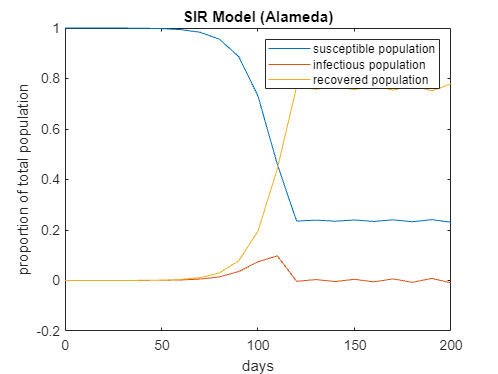

%Euler's Method
dt = 10;			% let delta t = 10 days 
tspan = 0:dt:200;		% let t range up to 200 days
POP(:,1) = pop0;		% POP is the matrix of population data
for i = 1:(200/dt)		% forward euler in a for loop
    POP(:,i+1) = POP(:,i) + dt * SIRmodel(tspan, POP(:,i),beta,mu);
end

% Display a graphical solution of s, i, and r (POP(1,:), POP(2,:),POP(3,:)) 
% on a single plot. Write the commands in the space below. Add all
% formatting to the plot to make sure it is readable and appropriate.


plot(tspan, POP(1, :), tspan, POP(2, :), tspan, POP(3, :));
legend('susceptible population', 'infectious population', 'recovered population');
xlabel('days');
ylabel('proportion of total population');
title('SIR Model (Alameda)');

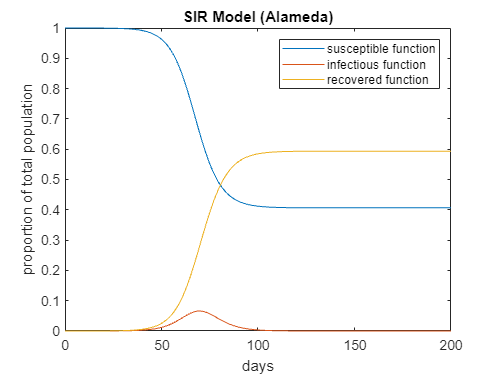

dt = 1;			        % let delta t= 10 days 
tspan = 0:dt:200;		% let t range up to 200 days
POP(:,1) = pop0;		% POP is the matrix of population data
for i = 1:(200/dt)		% forward euler in a for loop
    		POP(:,i+1) = POP(:,i) + dt * SIRmodel(tspan, POP(:,i),beta,mu);
end

% Display a graphical solution of s, i, and r (POP(1,:), POP(2,:),POP(3,:)) 
% on a single plot. Write the commands in the space below. Add all
% formatting to the plot to make sure it is readable and appropriate.

plot(tspan, POP(1, :), tspan, POP(2, :), tspan, POP(3, :));
legend('susceptible function', 'infectious function', 'recovered function');
xlabel('days');
ylabel('proportion of total population');
title('SIR Model (Alameda)');

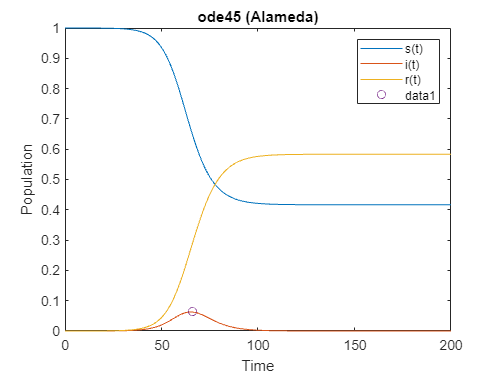


[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3))
xlabel('Time')
ylabel('Population')
title('ode45 (Alameda)')
legend('s(t)','i(t)','r(t)')
% find the maximum of the infected population (both the value and the location in the array)
[maxinfec, maxloc] = max(pop(:, 2));
% max infection value = 0.0660 and max infection index = 81

% plot the location and value of the maximum as a single (x,y) coordinate pair on the previous plot
hold on
plot(maxloc, maxinfec, 'o')
hold off


beta = 0.8

beta = 0.8000

[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
subplot(2,1,1)
plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3))
xlabel('Time')
ylabel('Population')
title('ode45')
legend('s(t)','i(t)','r(t) (Alameda)')
figure
% Below: Store values for peak ratio at different beta values
j = 1

j = 1

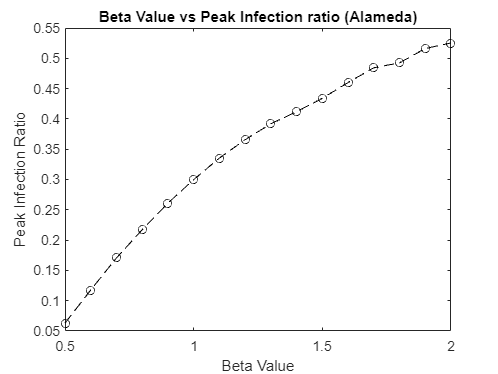

for i = 0.5:.1:2.0
    [t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,i,mu),tspan,pop0);
    [peak,loc] = max(pop(:,2));
    beta_n_peaks(j,:) = [i,peak];
    j=j+1;
end
% Include a plot command to plot the beta value on the x-axis and the 
% corresponding peak infection ratio on the y-axis
plot(beta_n_peaks(:, 1), beta_n_peaks(:, 2), 'k--o')
xlabel('Beta Value')
ylabel('Peak Infection Ratio')
title('Beta Value vs Peak Infection ratio (Alameda)')
hold off

beta = 1/2

beta = 0.5000

mu = 0.5

mu = 0.5000

[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
subplot(2,1,1)
plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3))
xlabel('Time')
ylabel('Population')
title('ode45 (Alameda)')
legend('s(t)','i(t)','r(t)')
figure
% Create a loop to store peak levels of the infected population and when
% they occur (mu values). Hint: You can adapt the loop in the code above.
k = 1

k = 1

for l = 0.1:0.05:0.6
    [t,pop2] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,l),tspan,pop0);
    [peak2,loc2] = max(pop2(:,2));
    mu_n_peaks(k,:) = [l,peak2];
    k=k+1;
end
% Include a plot command to plot the mu value on the x-axis and the 
% corresponding peak infection ratio on the y-axis
plot(mu_n_peaks(:, 1), mu_n_peaks(:, 2), 'k--o')
xlabel('Mu Value')
ylabel('Peak Infection Ratio')
title('Mu Value vs Peak Infection ratio (Alameda)')
hold off

% Input different values of mu and beta:
mu = 0.8

mu = 0.8000

beta = 1.1

beta = 1.1000


% Data from Part 1:
death = [14 28 50 66 156 190 156 108 68 77 33 65 24];
weeks = 1:13;
% Plot the data and the model fit together:
figure
subplot(2,1,1)
plot(weeks*7,death,'o') % I multiplied weeks by seven to scale the the x-axis appropriately
title('Plot of HK excess influenza deaths')
subplot(2,1,2)
[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
plot(tspan,pop(:,2))
xlabel('Time')
ylabel('Population')
title('ode45 (Alameda)')



%NEW YORK
clear;clc;close all
NYpop = 8773000; % population of AC at day 0 of the outbreak
pop0 = [1-(10/NYpop),10/NYpop,0];
mu = 1/3;
beta = 1/2;
SIRmodel([],pop0,beta,mu)

ans = 1.0e-06 *

   -0.5699
    0.1900
    0.3800


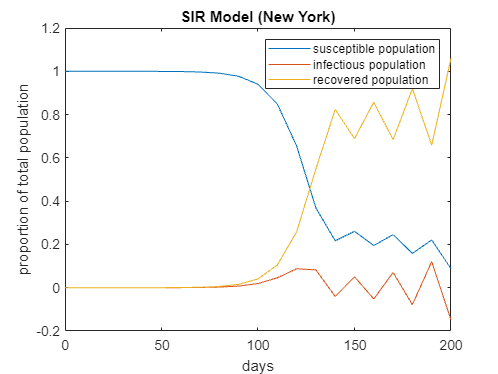

%Euler's Method
dt = 10;			% let delta t = 10 days 
tspan = 0:dt:200;		% let t range up to 200 days
POP(:,1) = pop0;		% POP is the matrix of population data
for i = 1:(200/dt)		% forward euler in a for loop
    POP(:,i+1) = POP(:,i) + dt * SIRmodel(tspan, POP(:,i),beta,mu);
end

% Display a graphical solution of s, i, and r (POP(1,:), POP(2,:),POP(3,:)) 
% on a single plot. Write the commands in the space below. Add all
% formatting to the plot to make sure it is readable and appropriate.


plot(tspan, POP(1, :), tspan, POP(2, :), tspan, POP(3, :));
legend('susceptible population', 'infectious population', 'recovered population');
xlabel('days');
ylabel('proportion of total population');
title('SIR Model (New York)');

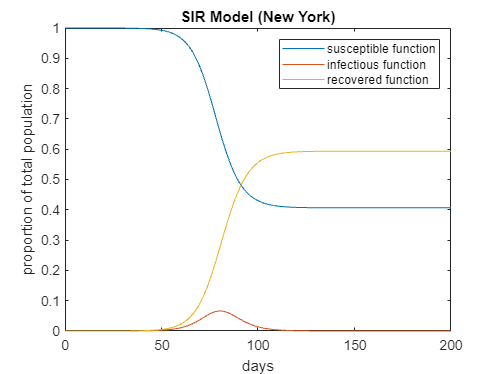

dt = 1;			        % let delta t= 10 days 
tspan = 0:dt:200;		% let t range up to 200 days
POP(:,1) = pop0;		% POP is the matrix of population data
for i = 1:(200/dt)		% forward euler in a for loop
    		POP(:,i+1) = POP(:,i) + dt * SIRmodel(tspan, POP(:,i),beta,mu);
end

% Display a graphical solution of s, i, and r (POP(1,:), POP(2,:),POP(3,:)) 
% on a single plot. Write the commands in the space below. Add all
% formatting to the plot to make sure it is readable and appropriate.

plot(tspan, POP(1, :), tspan, POP(2, :), tspan, POP(3, :));
legend('susceptible function', 'infectious function', 'recovered function');
xlabel('days');
ylabel('proportion of total population');
title('SIR Model (New York)');

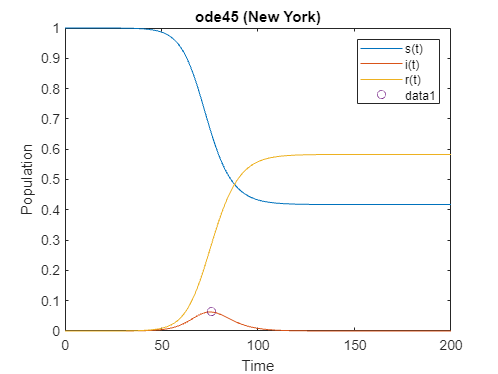


[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3))
xlabel('Time')
ylabel('Population')
title('ode45 (New York)')
legend('s(t)','i(t)','r(t)')
% find the maximum of the infected population (both the value and the location in the array)
[maxinfec, maxloc] = max(pop(:, 2));
% max infection value = 0.0660 and max infection index = 81

% plot the location and value of the maximum as a single (x,y) coordinate pair on the previous plot
hold on
plot(maxloc, maxinfec, 'o')
hold off


beta = 1.9

beta = 1.9000

[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
subplot(2,1,1)
plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3))
xlabel('Time')
ylabel('Population')
title('ode45 (New York)')
legend('s(t)','i(t)','r(t)')
figure
% Below: Store values for peak ratio at different beta values
j = 1

j = 1

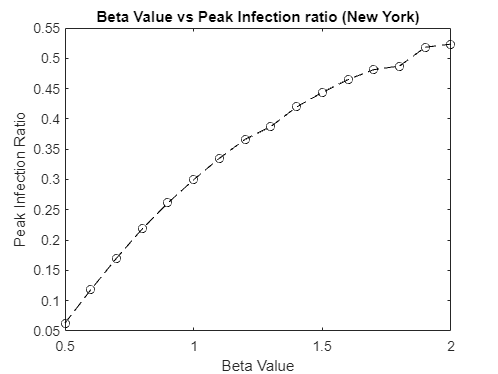

for i = 0.5:.1:2.0
    [t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,i,mu),tspan,pop0);
    [peak,loc] = max(pop(:,2));
    beta_n_peaks(j,:) = [i,peak];
    j=j+1;
end
% Include a plot command to plot the beta value on the x-axis and the 
% corresponding peak infection ratio on the y-axis
plot(beta_n_peaks(:, 1), beta_n_peaks(:, 2), 'k--o')
xlabel('Beta Value')
ylabel('Peak Infection Ratio')
title('Beta Value vs Peak Infection ratio (New York)')
hold off

beta = 1/2

beta = 0.5000

mu = 0.15

mu = 0.1500

[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
subplot(2,1,1)
plot(tspan,pop(:,1),tspan,pop(:,2),tspan,pop(:,3))
xlabel('Time')
ylabel('Population')
title('ode45 (New York)')
legend('s(t)','i(t)','r(t)')
figure
% Create a loop to store peak levels of the infected population and when
% they occur (mu values). Hint: You can adapt the loop in the code above.
k = 1

k = 1

for l = 0.1:0.05:0.6
    [t,pop2] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,l),tspan,pop0);
    [peak2,loc2] = max(pop2(:,2));
    mu_n_peaks(k,:) = [l,peak2];
    k=k+1;
end
% Include a plot command to plot the mu value on the x-axis and the 
% corresponding peak infection ratio on the y-axis
plot(mu_n_peaks(:, 1), mu_n_peaks(:, 2), 'k--o')
xlabel('Mu Value')
ylabel('Peak Infection Ratio')
title('Mu Value vs Peak Infection ratio (New York)')
hold off

% Input different values of mu and beta:
mu = 0.8

mu = 0.8000

beta = 1.1

beta = 1.1000


% Data from Part 1:
death = [14 28 50 66 156 190 156 108 68 77 33 65 24];
weeks = 1:13;
% Plot the data and the model fit together:
figure
subplot(2,1,1)
plot(weeks*7,death,'o') % I multiplied weeks by seven to scale the the x-axis appropriately
title('Plot of HK excess influenza deaths (New York)')
subplot(2,1,2)
[t,pop] = ode45(@(t,pop0)SIRmodel(t,pop0,beta,mu),tspan,pop0);
plot(tspan,pop(:,2))
xlabel('Time')
ylabel('Population')
title('ode45 (New York)')

%3 
%ALAMEDA
clear;clc;close all
% Calculate Ro by estimating s at infinity, s(inf)
sinf = 0.44; % based on our estimates for susceptible population over time s(inf)
R0test = log(sinf)/(sinf-1)

R0test = 1.4660

% Calculate Ro by using Ro = beta/mu
betatest = 1.5;
mutest = 1;
R0 = betatest/mutest 

R0 = 1.5000

%the beta value is 1.5 and the mu is 1
%the predicted r-naught value is 1.4660 and the actual value is 1.5 

%NEW YORK
clear;clc;close all
% Calculate Ro by estimating s at infinity, s(inf)
sinf = 0.42; % based on our estimates for susceptible population over time s(inf)
R0test = log(sinf)/(sinf-1)

R0test = 1.4957

% Calculate Ro by using Ro = beta/mu
betatest = 2.8;
mutest = 0.9;
R0 = betatest/mutest

R0 = 3.1111

%the beta value is 2.8 and the mu is 0.9
%the predicted r-naught value is 1.4957 and the actual value is 3.1111,
%this one is much higher since there was more covid cases in New York

%2 In Alameda the best fit values for beta and mu are 1.5 and 1 respectedly.
% For New York the beta and mu values are 2.8 and 0.9. The New York ones
% are higher mainly because of the more dense population in New York
% County.
%3 The two values for r-naught for Alameda county are 1.4660 which is the
%predicted value and 1.5 which is the actual R-naught value. For New york
%the two R-naught values are 1.4957 and the actual value is 3.1111. 
% New york has a higher R-Naught value because of its higher population and
% its more dense population.

clear;clc;close all
% Alameda SIRModel2 test
Apop = 1685886; % population of AC at day 0 of the outbreak
pop0 = [1-(10/Apop),10/Apop,0, 0];
mu = 1;
beta = 1.5;
p = (Apop-1539202)/Apop;       %percentage of people who were unvaccinated and still succeptible to covid
SIRmodel2([],pop0,beta,mu,p)

ans = 1.0e-05 *

   -0.8897
    0.5932
    0.5932



apd=2091/36594                  %amount of confirmed deaths divided confirmed cases

apd = 0.0571

SIRM([],pop0,beta,mu,p,apd)

ans = 1.0e-05 *

   -0.8897
    0.2627
    0.5932
    0.0339



%https://ourworldindata.org/mortality-risk-covid
%https://covid-19.acgov.org/data.page?

Alameda_covid_data = readtable("ENGR_25_COVID_DATA_2.xlsx")

Alameda_covid_data = 1746×24 table
       date           area        area_type     population    cases    cumulative_cases    deaths    cumulative_deaths    total_tests    cumulative_total_tests    positive_tests    cumulative_positive_tests    reported_cases    cumulative_reported_cases    reported_deaths    cumulative_reported_deaths    reported_tests    Administered_Dose1_Recip_18PlusPop_Pct    GovernmentIntervention    Var20      Var21         Var22         Var23       total_adult_patients_hospitalized_confirmed_and_suspected_covid
    ___________    ______

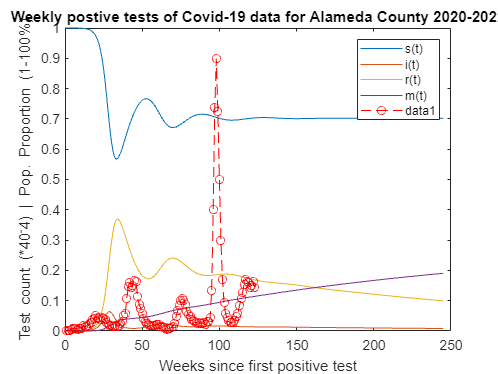

Apostests = table2array(Alameda_covid_data(28:1742, "positive_tests"));
Adeaths = table2array(Alameda_covid_data(28:1742, "deaths"));
weeks = 1:length(Apostests)/7;
postestweekly = reshape(sum(reshape(Apostests,7,[])),[],1)';
deathsweekly = reshape(sum(reshape(Adeaths,7,[])),[],1)';

%Euler's Method
dt = 1;			% let delta t = 1 week
tspan = 0:dt:245;		% let t range up to weeks
POP(:,1) = pop0;		% POP is the matrix of population data
for i = 1:(245/dt)		% forward euler in a for loop
    POP(:,i+1) = POP(:,i) + dt * SIRM(tspan, POP(:,i),beta,mu, p, apd);
end

% Display a graphical solution of s, i, and r (POP(1,:), POP(2,:),POP(3,:)) 
% on a single plot. Write the commands in the space below. Add all
% formatting to the plot to make sure it is readable and appropriate.


plot(tspan, POP(1, :), tspan, POP(2, :), tspan, POP(3, :), tspan, POP(4, :));
xlabel('days');
ylabel('proportion of total population');
title('SIRM MODEL w/ positive cases for Alameda County')
legend('s(t)','i(t)','r(t)', 'm(t)')
hold on
plot(weeks, postestweekly/40000, 'r--o');
xlabel('Weeks since first positive test');
ylabel('Test count (*40^-4) | Pop. Proportion (1-100%)');
title('Weekly postive tests of Covid-19 data for Alameda County 2020-2022');
hold off

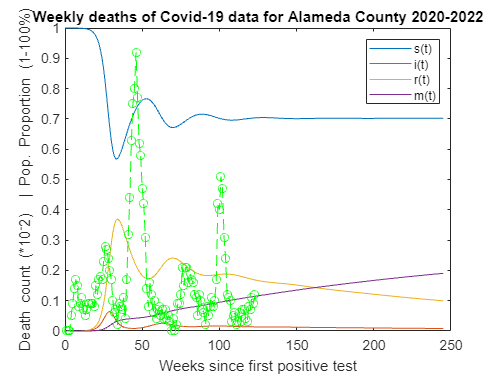


plot(tspan,POP(1,:),tspan,POP(2, :),tspan,POP(3, :), tspan, POP(4, :))
xlabel('Time')
ylabel('Population')
title('SIRM MODEL w/ deaths for Alameda County')
legend('s(t)','i(t)','r(t)', 'm(t)')
hold on
plot(weeks, deathsweekly/100, 'g--o');
xlabel('Weeks since first positive test');
ylabel('Death count (*10^-2)  | Pop. Proportion (1-100%)');
title('Weekly deaths of Covid-19 data for Alameda County 2020-2022');
hold off

clear;clc;close all
% Alameda SIRModel2 test
NYpop = 8773000; % population of AC at day 0 of the outbreak
pop0 = [1-(10/NYpop),10/NYpop,0, 0];
mu = 0.9;
beta = 2.8;
p = (NYpop-7438811)/NYpop;       %percentage of people who were unvaccinated and still succeptible to covid
SIRmodel2([],pop0,beta,mu,p)

ans = 1.0e-05 *

   -0.3192
    0.1026
    0.1026



NYpd= 43564/3078675;                  %amount of confirmed deaths divided confirmed cases
SIRM([],pop0,beta,mu,p,NYpd)

ans = 1.0e-05 *

   -0.3192
    0.2151
    0.1026
    0.0015



%https://ourworldindata.org/mortality-risk-covid
%https://covid-19.acgov.org/data.page?

Newyork_covid_data = readtable('ENGR_25_COVID_DATA_2.xlsx','Sheet','New York City');

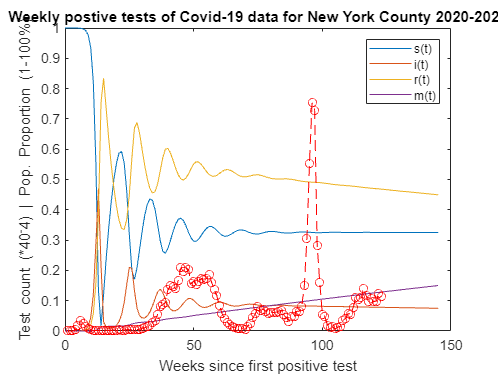

NYpostests = table2array(Newyork_covid_data(41:2868,"pnew_case"));
NYdeaths = table2array(Newyork_covid_data(41:2868,"new_death"));

weeks = 1:length(NYpostests)/7;
% convert column daily values to row vectors by week
NYpostestweekly = reshape(sum(reshape(NYpostests,7,[])),[],1)';
NYdeathsweekly = reshape(sum(reshape(NYdeaths,7,[])),[],1)';

%Euler's Method
dt = 1;			% let delta t = 1 week
tspan = 0:dt:145;		% let t range up to 145 weeks
NYPOP(:,1) = pop0;		% POP is the matrix of population data
for i = 1:(145/dt)		% forward euler in a for loop
    NYPOP(:,i+1) = NYPOP(:,i) + dt * SIRM(tspan, NYPOP(:,i),beta,mu, p, NYpd);
end

% Display a graphical solution of s, i, and r (POP(1,:), POP(2,:),POP(3,:)) 
% on a single plot. Write the commands in the space below. Add all
% formatting to the plot to make sure it is readable and appropriate.


plot(tspan, NYPOP(1, :), tspan, NYPOP(2, :), tspan, NYPOP(3, :), tspan, NYPOP(4, :));
xlabel('days');
ylabel('proportion of total population');
title('SIRM MODEL w/ positive cases for New York County')
legend('s(t)','i(t)','r(t)', 'm(t)')
hold on
plot(weeks, NYpostestweekly/40000, 'r--o');
xlabel('Weeks since first positive test');
ylabel('Test count (*40^-4) | Pop. Proportion (1-100%)');
title('Weekly postive tests of Covid-19 data for New York County 2020-2022');
hold off

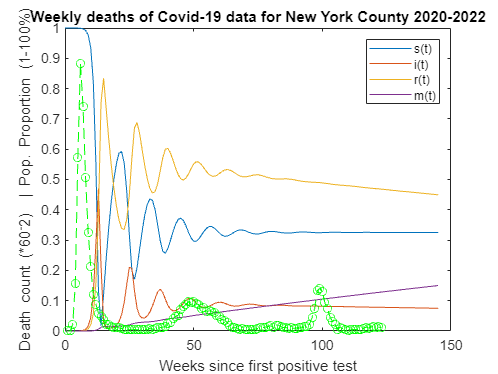


plot(tspan,NYPOP(1,:),tspan,NYPOP(2, :),tspan,NYPOP(3, :), tspan, NYPOP(4, :))
xlabel('Time')
ylabel('Population')
title('SIRM MODEL w/ deaths for New York County')
legend('s(t)','i(t)','r(t)', 'm(t)')
hold on
plot(weeks, NYdeathsweekly/6000, 'g--o');
xlabel('Weeks since first positive test');
ylabel('Death count (*60^-2)  | Pop. Proportion (1-100%)');
title('Weekly deaths of Covid-19 data for New York County 2020-2022');
hold off

% 5
% Peak infections for COVID 35 weeks after the first positive case (around
% 35 weeks after Feb 27th 2020). This time period seems reasonable as we
% tested various p values for the those who are capable of being infected
% again and still remain part of the susceptible population (unvaccinated)

% New York on the other hand had a severe difference in spread rate and
% most likely had an earlier peak in infections compared to the graph as
% deaths occurred fairly early on with quick spread. Our estimated peak
% based on the SIRM model would be around 15 weeks after the first positive
% case, but in reality this would be much faster around 10 weeks.

% 6
% The end of the pandemic for Alameda could be around 300 weeks after the first positive case
% given the gradual mu value and the slow spread of the disease throughout time. Even
% recent information on Alameda County has shown new cases occuring every
% few months and mandates still happening within this year. Any uncertainty
% could be caused by the lack of people getting tested in recent weeks
% and/or a lower beta value over time given the changes in COVID strain

% New York has a much higher R0 value making the spread quick but also the
% recovery just as fast over time. The projected end of the pandemic could
% even be considered current as 145 weeks after the pandemic (around first
% week of Dec. 2022). Any uncertainty would be another spike in spread from
% either a new strain or unvaccinated population, although highly unlikely.


%7
clear; clc; close all;
% Calculate R0 for Alameda and NY

AR0 = 1.5/1; % beta/mu
NYR0 = 2.8/0.9;

% Since we want to determine the fraction of the population that needs to be inocculated 
% in order to ensure that no epidemic will occur we can use the
% herd immunity threshold forumla to simplify the given formula.


% The logic is as follows to determine the threshold formula:

% If the initial susceptible population proportion (so) must be less than 1/R0 in
% order to prevent an epidemic, that means those who are immune to the
% infection must be equal to 1 - so. 

% Using this basis, the population that needs to be immune or innoculated
% must be greater than proportion of 1 - 1/R0.

% Therefore, 1 - so > 1 - 1/R0
% (initial innoculated/immune population) > (Population proportion not immune)

% determine vaccine infection prevention effectiveness based on variants
% using data from healthdata.org for vaccine efficacy averaged per each
% major variant: https://www.healthdata.org/covid/covid-19-vaccine-efficacy-summary

% D614G (ancestral type), P.1 (Gamma), B.1.617.2 (Delta), and B.1.1.529 (Omicron).
D614Gi0 = 0.75;
Gammai0 = 0.72;
Deltai0 = 0.73;
Omicroni0 = 0.40;
Avgi0 = (D614Gi0 + Gammai0 + Deltai0 + Omicroni0)/4;

% plug in these values we get:
Ainocfrac = 1 - (1/AR0)*Avgi0;
NYinofrac = 1 - (1/NYR0)*Avgi0;

% We would need approximately 57% of the population for Alameda 
% and 79% of New York to be inocculated to
% prevent an epidemic given a 65% effective vaccine throughout all variants 
% and average consumer vaccine effectiveness.


% Sources: 
% https://www.healthdata.org/covid/covid-19-vaccine-efficacy-summary 
% https://academic.oup.com/cid/article/52/7/911/299077
% https://plus.maths.org/content/maths-minute-r0-and-herd-immunity